pi=3.1416

pi = 3.1416

gmx = [0,0,4,4,0,0,4,4,0,4,0.4,3.6,2,2]';
gmy = [1.5,1.5,1.5,1.5,3.5,3.5,3.5,3.5,4.7,4.7,5,5,4.0,4.0]';
gmth = [pi,0,pi,0,pi,0,pi,0,0,pi,-pi/2,-pi/2,pi,0]';
gms = [gmx gmy gmth]

gms =          0    1.5000    3.1416
         0    1.5000         0
    4.0000    1.5000    3.1416
    4.0000    1.5000         0
         0    3.5000    3.1416
         0    3.5000         0
    4.0000    3.5000    3.1416
    4.0000    3.5000         0
         0    4.7000         0
    4.0000    4.7000    3.1416


% bottom left
x1 = [0 0];
y1 = [1.8 0];
% bottom right
x2 = [2.2 0];
y2 = [4.0 0.0];
% top left
x3 = [0.0 5.0];
y3 = [1.8 5.0];
% top right
x4 = [2.2 5.0];
y4 = [4.0 5.0];
% left down
x5 = [0.0 0.0];
y5 = [0.0 1.8];
% left up
x6 = [0.0 3.2];
y6 = [0.0 5.0];
% right down
x7 = [4.0 0.0];
y7 = [4.0 1.8];
% right up
x8 = [4.0 3.2];
y8 = [4.0 5.0];
% maze bottom left
x9 = [0.9 3.1];
y9 = [1.7 3.1];
% maze bottom right
x10 = [2.3 3.1];
y10 = [3.1 3.1];
% maze left down
x11 = [1.7 2.5];
y11 = [1.7 3.1];
% maze left up
x12 = [0.9 3.1];
y12 = [0.9 4.3];
% maze right down
x13 = [2.3 2.5];
y13 = [2.3 3.1];
% maze right up
x14 = [3.1 3.1];
y14 = [3.1 4.3];
% maze middle horizontal
x15 = [1.5 3.7];
y15 = [2.5 3.7];
% maze middle vertical
x16 = [2.0 3.7];
y16 = [2.0 4.3];
% maze top
x17 = [0.9 4.3];
y17 = [3.1 4.3];

line_xs = [x1;x2;x3;x4;x5;x6;x7;x8;x9;x10;x11;x12;x13;x14;x15;x16;x17];
line_ys = [y1;y2;y3;y4;y5;y6;y7;y8;y9;y10;y11;y12;y13;y14;y15;y16;y17];

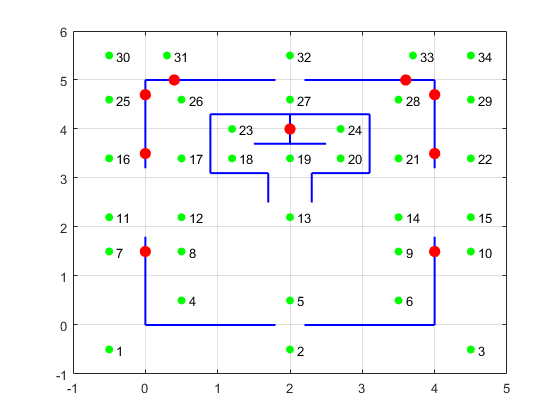

nodes = [-0.5,-0.5; 2,-0.5; 4.5,-0.5; % Nodes in the level of y = -0.5
            0.5,0.5; 2,0.5; 3.5,0.5; % y = 0.5
            -0.5,1.5; 0.5,1.5; 3.5,1.5; 4.5,1.5; % y = 1.5
            -0.5,2.2; 0.5,2.2; 2,2.2; 3.5,2.2; 4.5,2.2; % y=2.2
            -0.5,3.4; 0.5,3.4; 1.2,3.4; 2,3.4; 2.7,3.4; 3.5,3.4; 4.5,3.4;% y = 3.4
            1.2,4; 2.7,4; % y=4
             -0.5,4.6; 0.5,4.6; 2,4.6; 3.5,4.6; 4.5,4.6; % y= 4.6
             -0.5,5.5; 0.3,5.5; 2,5.5; 3.7,5.5; 4.5,5.5; % y = 5.5
             ];
num = size(nodes);
num = num(1);
figure
% Draw walls
for i = 1:17
    pt1 = line_xs(i,:);
    pt2 = line_ys(i,:);
    grid on
    plot([pt1(1) pt2(1)], [pt1(2) pt2(2)],"LineWidth",1.5,"Color",'b')
    hold on
end
% Draw guidemarks
scatter(gms(:,1),gms(:,2),72,'red',"filled")
% Draw nodes
scatter(nodes(:,1),nodes(:,2),36,'green','filled')
% Add labels
labels = string(1:num);
text(nodes(:,1)+0.1,nodes(:,2),labels);
% Set axis ranges
axis([-1 5 -1 6])
hold off